**Lecture HW3**

Steven Henderson

**Question 4**

A baseball has been batted and is moving in air. It is subject to drag that is quadratic in the velocity Fd = −cv2 ˆv = −cvv. Use the following parameters: c = 1 2 CD ρ d2, CD = 0.47, diameter d = 74 mm, mass = 145 g, initial speed = 45 m/s, initial angle = 30 degrees, ρair = 1.2 kg/m3, and initial position (x, z) = (0, 1) m.

1. Derive the differential equations for the position x(t) and z(t).


$$\begin{array}{l}
F_d =-\mathrm{cv}\vec{v} =m\frac{d\vec{v} }{\mathrm{dt}}\\
\frac{{\mathrm{dv}}_x }{\mathrm{dt}}=-\frac{c}{m}v_x \vec{v} =\frac{{\mathrm{dx}}^2 }{d^2 t}\\
\frac{{\mathrm{dv}}_z }{\mathrm{dt}}=-g-\frac{c}{m}v_z \vec{v} =\frac{{\mathrm{dz}}^2 }{d^2 t}\\
\vec{v} =\sqrt{v_x^2 +v_z^2 }
\end{array}$$


2. Write a MATLAB livescript to find the speeds and positions vx(t), vz (t), x(t), z(t). Use enough time to ensure the object hits the ground. Give plots of each of the four quantities (as a function of time), and add aplot showing z as a function of x. You might be tempted to use your code from your earlier solution, but see the note at the end.

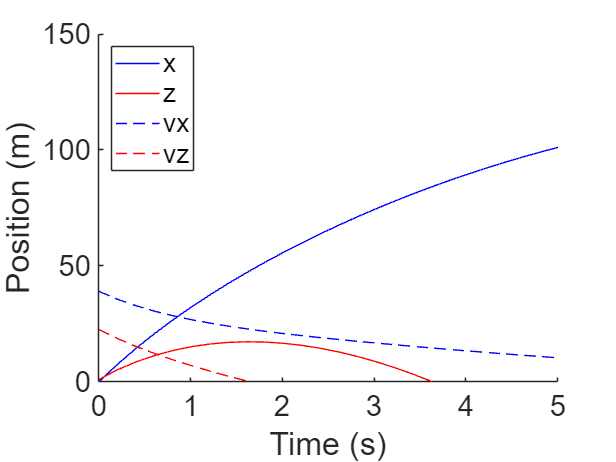

function out = drag(t, pos)
    CD = 0.47 ;
    rho = 1.2 ;
    d = 74 / 1000 ;
    m = 145 / 1000 ;
    c = (1/2)*CD*rho*d^2 ;
    g = 10 ;

    x = pos(1) ;
    vx = pos(2) ;
    z = pos(3) ;
    vz = pos(4) ;

    f1 = -(c/m)*vx*sqrt(vx^2 + vz^2) ;
    f2 = -g - (c/m)*vz*sqrt(vx^2 + vz^2) ;

    out = [vx; f1; vz; f2] ;
end
iv = 45 ;
iphi = 30 ;
ipos = [0; iv*cosd(iphi); 1; iv*sind(iphi)] ;

tspan = linspace(0, 20, 100) ;

[t, pos] = ode45(@drag, tspan, ipos) ;

x_sol = pos(:, 1) ;
vx_sol = pos(:, 2) ;
z_sol = pos(:, 3) ;
vz_sol = pos(:, 4) ;

clf
hold on
plot(tspan, x_sol, 'b')
plot(tspan, z_sol, 'r') 
plot(tspan, vx_sol, 'b--')
plot(tspan, vz_sol, 'r--')
hold off
ylabel('Position (m)')
xlabel('Time (s)')
ylim([0, 150])
xlim([0, 5])
legend('x', 'z', 'vx', 'vz', 'Location', 'northwest')
set(gca, 'fontsize', 20) ;

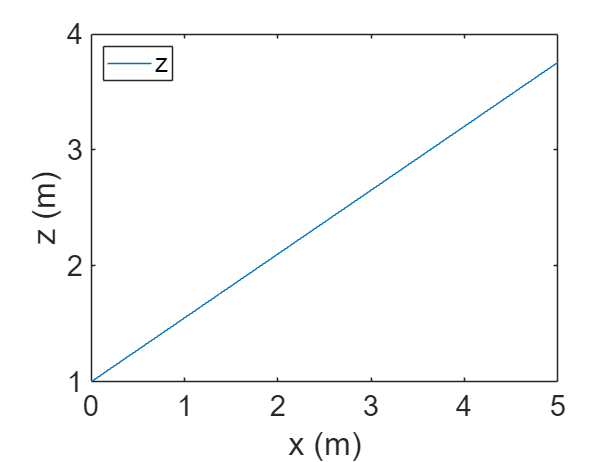

clf
plot(x_sol, z_sol)
ylabel('z (m)')
xlabel('x (m)')
%ylim([0, 150])
xlim([0, 5])
legend('z', 'Location', 'northwest')
set(gca, 'fontsize', 20) ;

3. Demonstrate that your code is correct (or that the results make sense) by comparing your derived position (x(t) and z(t)) to the position in the case of no drag. That is, overlay the positions and velocities with no drag in all the plots you generated earlier. Give two sentences explaining why you conclude that your results make sense.


$$\begin{array}{l}
\frac{{\mathrm{dx}}^2 }{d^2 t}=0\\
\frac{{\mathrm{dz}}^2 }{d^2 t}=-g
\end{array}$$


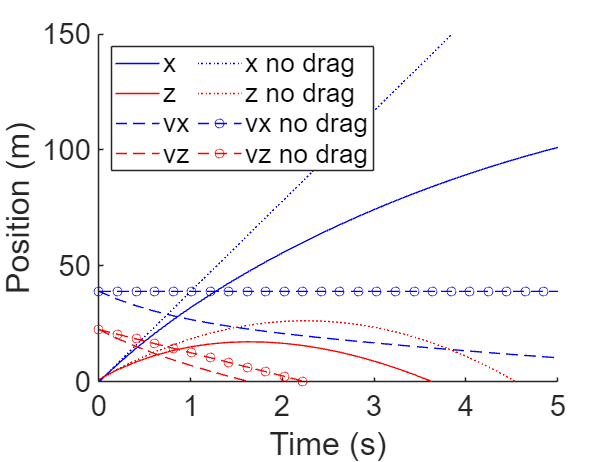

function out = nodrag(t, pos)
    g = 10 ;

    x = pos(1) ;
    vx = pos(2) ;
    z = pos(3) ;
    vz = pos(4) ;

    f1 = 0 ;
    f2 = -g ;

    out = [vx; f1; vz; f2] ;
end

[t, pos_nodrag] = ode45(@nodrag, tspan, ipos) ;

x_sol_nodrag = pos_nodrag(:, 1) ;
vx_sol_nodrag = pos_nodrag(:, 2) ;
z_sol_nodrag = pos_nodrag(:, 3) ;
vz_sol_nodrag = pos_nodrag(:, 4) ;

clf
hold on 
plot(tspan, x_sol, 'b')
plot(tspan, z_sol, 'r') 
plot(tspan, vx_sol, 'b--')
plot(tspan, vz_sol, 'r--')
plot(tspan, x_sol_nodrag, 'b:')
plot(tspan, z_sol_nodrag, 'r:') 
plot(tspan, vx_sol_nodrag, 'b--o')
plot(tspan, vz_sol_nodrag, 'r--o')
hold off
ylabel('Position (m)')
xlabel('Time (s)')
ylim([0, 150])
xlim([0, 5])
legend('x', 'z', 'vx', 'vz', 'x no drag', 'z no drag', 'vx no drag', 'vz no drag', 'Location', 'northwest', 'NumColumns', 2)
set(gca, 'fontsize', 20) 

This looks good as each of the positions and velocities for the solution with no drag follow the same paths as the positions and velocities of the solution with drag. Each of the positions and velocities for the no drag solution are slightly larger than the solutions with drag which makes sense as without drag the object would fly further and move faster. Another note is to notice the x velocity of the no drag solution is constant which makes sense as there would be no forces acting upon it in the x direction.

4. Find the initial angle at which the ball needs to be batted to achieve maximum range, and compare it to the angle for the case of no drag. Since the batter can only aim crudely, find this angle to within ∼ ±2.5 deg (a span of about 5 degrees), and give the range. Be sure to explain how you found the span in angle and the range. Compare to the range and the angle for maximum range without drag. Give approximate values and explain how you obtained them. The phrase ‘maximum range’ refers to the distance on the ground from (x, z) = (0, 1) m to (xrange, z = 0) m.

function [range_index, x_sol, vx_sol, z_sol, vz_sol] = find_range(iphi, iv, ix, iz, tspan)
    ipos = [ix; iv*cosd(iphi); iz; iv*sind(iphi)] ;

    [t, pos] = ode45(@drag, tspan, ipos) ;

    x_sol = pos(:, 1) ;
    vx_sol = pos(:, 2) ;
    z_sol = pos(:, 3) ;
    vz_sol = pos(:, 4) ;

    for i = 1:length(z_sol)
        if z_sol(i) <= 0
            range_index = i ;
        end
    end
end

function [angle, range, x_vals, vx_vals, z_vals, vz_vals] = find_angle(span_angles, iv, ix, iz, tspan)
    ranges = zeros(1, length(span_angles)) ;
    x_vals = zeros(length(tspan)) ;
    vx_vals = zeros(length(tspan)) ;
    z_vals = zeros(length(tspan)) ;
    vz_vals = zeros(length(tspan)) ;

    for i = 1:length(span_angles)
        [range_index, x_sol, vx_sol, z_sol, vz_sol] = find_range(span_angles(i), iv, ix, iz, tspan) ;
        x_vals(:, i) = x_sol ;
        vx_vals(:, i) = vx_sol ;
        z_vals(:, i) = z_sol ;
        vz_vals(:, i) = vz_sol; 
        ranges(:, i) = x_sol(range_index, :) ;
    end
    [range, idx] = max(ranges) ;
    angle = span_angles(idx) ;
end

span_angles = 0:0.5:90 ;
iv = 45 ;
ix = 0 ;
iz = 1;
[angle, range, x_vals, vx_vals, z_vals, vz_vals] = find_angle(span_angles, iv, ix, iz, tspan) ;
disp(['Max range angle: ', num2str(angle), ' Max range: ', num2str(range)]) ;

Max range angle: 12.5 Max range: 140.9242


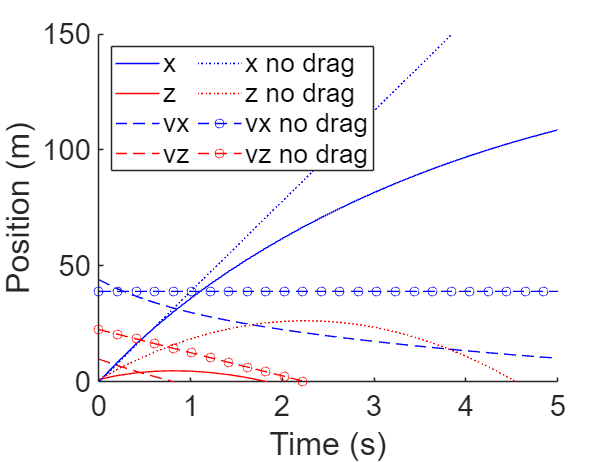


[t, max_range] = ode45(@drag, tspan, [ix, iv*cosd(angle), iz, iv*sind(angle)]) ;

x_sol_max_range = max_range(:, 1) ;
vx_sol_max_range = max_range(:, 2) ;
z_sol_max_range = max_range(:, 3) ;
vz_sol_max_range = max_range(:, 4) ;

clf
hold on 
plot(tspan, x_sol_max_range, 'b')
plot(tspan, z_sol_max_range, 'r') 
plot(tspan, vx_sol_max_range, 'b--')
plot(tspan, vz_sol_max_range, 'r--')
plot(tspan, x_sol_nodrag, 'b:')
plot(tspan, z_sol_nodrag, 'r:') 
plot(tspan, vx_sol_nodrag, 'b--o')
plot(tspan, vz_sol_nodrag, 'r--o')
hold off
ylabel('Position (m)')
xlabel('Time (s)')
ylim([0, 150])
xlim([0, 5])
legend('x', 'z', 'vx', 'vz', 'x no drag', 'z no drag', 'vx no drag', 'vz no drag', 'Location', 'northwest', 'NumColumns', 2)
set(gca, 'fontsize', 20) 